This live script can be used to generate maps from Geosonsor data. It is used to generate the GPS performance comparison maps and the webmap for the field test data.

Author: Eike Trumann

Designed for Matlab R2017a including the Mapping Toolbox

Scatter plot for Nexus 7 GPS accuracy (without map in the background)

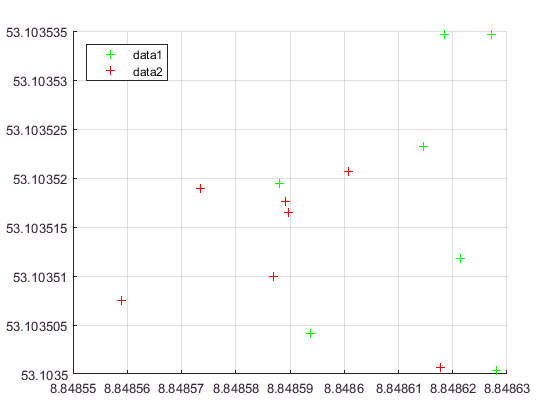

Error using gcm (line 25)
Not a map axes.

Error in getm (line 80)
gcm(maphndl);

Error in scaleruler>scalerulerOn (line 86)
if strcmp(getm(ax,'mapprojection'),'globe')

Error in 

GeoSensor0106Nexus7matlab = importfile('GeoSensor 01-06 Nexus 7 matlab.csv', 2, 28);
cla
place1 = [14 16 18 19 21 23 25];
hold all
mapshow(table2array(GeoSensor0106Nexus7matlab(place1,{'lat_0'})),table2array(GeoSensor0106Nexus7matlab(place1,{'lng_0'})),'DisplayType','Point','MarkerEdgeColor','g')
mapshow(table2array(GeoSensor0106Nexus7matlab(place1,{'lat_1'})),table2array(GeoSensor0106Nexus7matlab(place1,{'lng_1'})),'DisplayType','Point','MarkerEdgeColor','r')
grid on

legend({'Arduino GPS','Android GPS'},'Location','northwest')
hold off

Plot the localisation performance comparison data for the nexus 7 (fused only, offline) and Arduino GPS

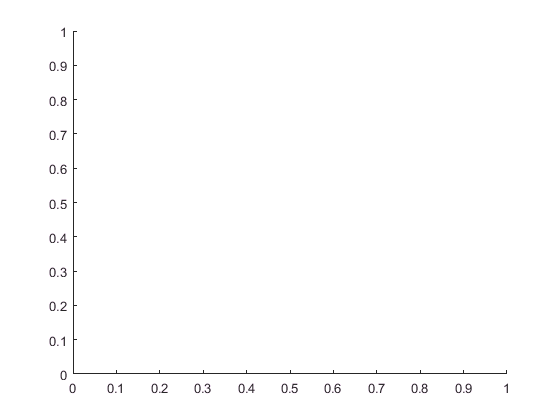

GeoSensor0106Nexus7matlab = importfile('GeoSensor 01-06 Nexus 7 matlab.csv', 2, 28);
place1 = [14:27];
hold all
webmap('Open Street Map')
wmmarker(table2array(GeoSensor0106Nexus7matlab(place1,{'lat_0'})),table2array(GeoSensor0106Nexus7matlab(place1,{'lng_0'})),'Color','g')
wmmarker(table2array(GeoSensor0106Nexus7matlab(place1,{'lat_1'})),table2array(GeoSensor0106Nexus7matlab(place1,{'lng_1'})))
wmzoom(18)
hold off

Plot the localisation performance comparison data for the Ulefone Power (fused provider (green), gps (blue), online (telekom) and WiFi active) and Arduino GPS (red)

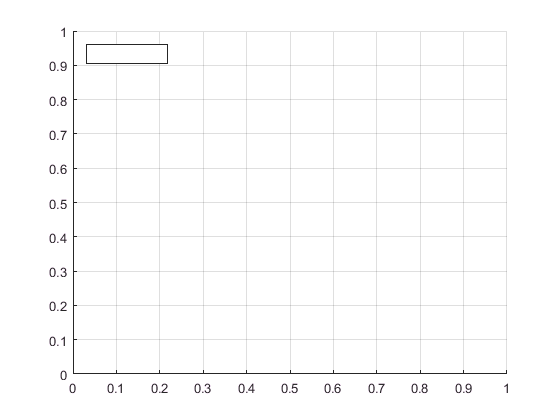

GeoSensor0106Ulefone = importfile('GeoSensor 01-06 Ulefone matlab.csv', 2, 20);
place1 = [1:15];
hold all
webmap('Open Street Map')
wmmarker(table2array(GeoSensor0106Ulefone(place1,{'lat_0'})),table2array(GeoSensor0106Ulefone(place1,{'lng_0'})),'Color','g')
wmmarker(table2array(GeoSensor0106Ulefone(place1,{'lat_1'})),table2array(GeoSensor0106Ulefone(place1,{'lng_1'})),'Color','b')
wmmarker(table2array(GeoSensor0106Ulefone(place1,{'lat_2'})),table2array(GeoSensor0106Ulefone(place1,{'lng_2'})))
wmzoom(17)
hold off

This visulises the markers generated for the system test (i.e. water temperatures in inland waters close to the university of Bremen).

matlabrc
GeoSensor0106Nexus7matlab = importfile('GeoSensor 01-06 Nexus 7 matlab.csv', 2, 28);
place1 = [1:13];
hold all
webmap('Open Street Map')
descriptions = cellstr(num2str(table2array(GeoSensor0106Nexus7matlab(place1,{'value_2'}))));
descriptions = strcat(descriptions,' °C');
time = cellstr(string(table2array(GeoSensor0106Nexus7matlab(place1,{'time_0'}))));
h = wmmarker(table2array(GeoSensor0106Nexus7matlab(place1,{'lat_2'})),table2array(GeoSensor0106Nexus7matlab(place1,{'lng_2'})),'FeatureName',descriptions,'Description',time)

h =   MarkerOverlay with no properties.


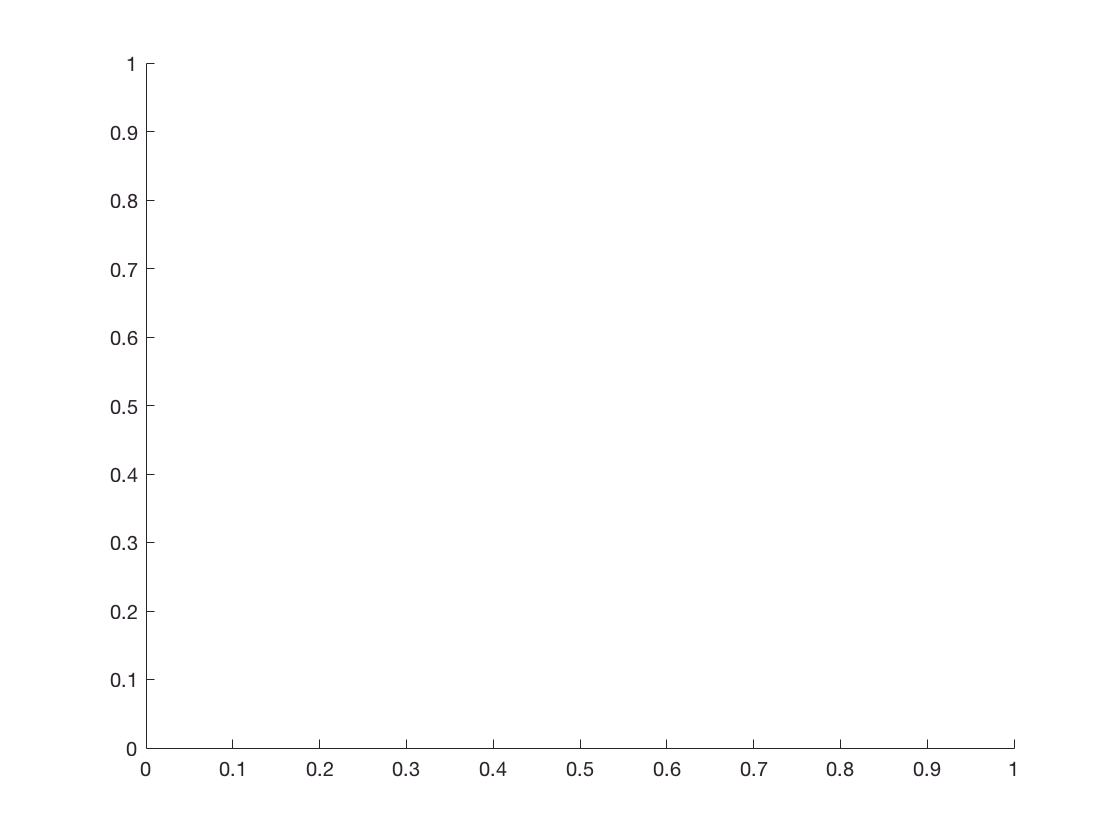

hold off

Show only Arduino GPS locations

matlabrc
GeoSensor0106Nexus7matlab = importfile('GeoSensor 01-06 Nexus 7 matlab.csv', 2, 28);
GeoSensor0106Ulefone = importfile('GeoSensor 01-06 Ulefone matlab.csv', 2, 20);
placeUle = [1:15];
placeNexus = [14:27];
hold all
webmap('Open Street Map')
wmmarker(table2array(GeoSensor0106Nexus7matlab(placeNexus,{'lat_0'})),table2array(GeoSensor0106Nexus7matlab(placeNexus,{'lng_0'})),'Color','g','IconScale',2)
wmmarker(table2array(GeoSensor0106Ulefone(placeUle,{'lat_0'})),table2array(GeoSensor0106Ulefone(placeUle,{'lng_0'})),'Color','g','IconScale',2)
hold off

hold all
webmap('Open Street Map')
wmmarker(table2array(GeoSensor0106Ulefone(placeUle,{'lat_2'})),table2array(GeoSensor0106Ulefone(placeUle,{'lng_2'})),'Color','y','IconScale',2)
wmmarker(table2array(GeoSensor0106Nexus7matlab(placeNexus,{'lat_1'})),table2array(GeoSensor0106Nexus7matlab(placeNexus,{'lng_1'})),'Color','k','IconScale',2)
[lat, lon] = scircle1(table2array(GeoSensor0106Ulefone(placeUle,{'lat_2'})),table2array(GeoSensor0106Ulefone(placeUle,{'lng_2'})),table2array(GeoSensor0106Ulefone(placeUle,{'accuracy_2'})),[],earthRadius('m')); 
wmline(lat,lon)
hold off

Calculate distances

GeoSensor0106Nexus7matlab = importfile('GeoSensor 01-06 Nexus 7 matlab.csv', 2, 28);
GeoSensor0106Ulefone = importfile('GeoSensor 01-06 Ulefone matlab.csv', 2, 20);
place1Ule = [1:2:15];
place1Nexus = [14 16 18 19 21 23 25 27];
place1lat = table2array(GeoSensor0106Nexus7matlab(place1Nexus,{'lat_0'}));
place1lat = cat(1, place1lat, table2array(GeoSensor0106Nexus7matlab(place1Ule,{'lat_0'})));
place1lng = table2array(GeoSensor0106Nexus7matlab(place1Nexus,{'lng_0'}));
place1lng = cat(1, place1lng, table2array(GeoSensor0106Nexus7matlab(place1Ule,{'lng_0'})));
lat_avg = mean(place1lat)

lat_avg = 53.1051

lng_avg = mean(place1lng)

lng_avg = 8.8447

dist_max = max(distance(lat_avg,lng_avg,place1lat,place1lng))

dist_max = 0.0083